clc; close all; clear all; warning off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

d_prime_s_res=0.2;  %% maximum distance resolution, m

tau_s_0=[0.0001,0.001,0.002,0.003,0.004,0.005,0.008,0.01,0.015,0.02]; %%  threshold in sensing

% r_c_com=1e9;  %% %% threshold/required data rate in communication, minimum communictaion data rate, 1Gbps

gamma_bs= 50/1000^2;  %%  density of base station, point/m^2

gamma_sct= 300/1000^2; %% density of SCT, point/m^2

gamma_st= 300/1000^2;   %% density of ST, point/m^2

eta=0.5;  %% first \beta part of the spectrum is allocated to sensing

mu=0.5;  %%  first \mu part of the power is allocated to sensing

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
run('parameters.mlx');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Ana_P_s_cov=zeros(length(tau_s_0),1);
Sim_P_s_cov=zeros(length(tau_s_0),1);

for tt=1:length(tau_s_0)
    
    tau_s=tau_s_0(1,tt)
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    L_cs1=@(d_tb) exp(-2*pi*gamma_bs*  integral(@(d_bjt) tau_s/(tau_s+(d_bjt/d_tb)^2)*d_bjt, d_tb, d_tb_max, "ArrayValued",true) );
    
    int_s1=@(d_tb,psi) integral(@(d_tit)  tau_s/(tau_s+  4*pi*d_tit^2*(d_tb^2+d_tit^2-2*d_tb*d_tit*cos(psi))/rho_sti/d_tb^2  *d_tit ), 0, d_tit_max, "ArrayValued",true );
    L_cs2=@(d_tb) exp(-gamma_st* integral(@(psi) int_s1(d_tb,psi), 0, 2*pi,"ArrayValued",true)  );
    
    int_s2= @(d_tb) exp(-tau_s*N_s/P_st/g_st/g_sr/rho_st/c^2/N_c/T_c*(4*pi)^3*f_s^2* d_tb^4  ) ...
        * L_cs1(d_tb)* L_cs2(d_tb)  *2*pi*gamma_bs*d_tb*exp(-pi*gamma_bs*d_tb^2);
    
    d_tb_max_prime=max(0,min(d_tb_max, c/2*(T_c-c*T_c/2/(B_s*1e6)/d_prime_s_res))); %% this is about the consideration of distance resolution
    
    Ana_P_s_cov(tt,1)= integral(@(d_tb) int_s2(d_tb), 0, d_tb_max_prime, "ArrayValued",true);
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    iteration=100000;
    
    SCNR_s=zeros(1,iteration);
    
    parfor ii=1:iteration
        
        d_tb_max_prime=max(0,min(d_tb_max, c/2*(T_c-c*T_c/2/(B_s*1e6)/d_prime_s_res))); %% this is about the consideration of distance resolution
        
        [D_tb,D_bjt,D_tit,D_bti]=calculate_clutter(range_xy_BS,range_xy_ST,gamma_bs,gamma_st,d_tb_max,d_tb_max_prime, d_bjt_max,d_tit_max,d_bti_max);
         
        C_s1= P_st*g_st/4/pi./D_bjt.^2  *rho_st/4/pi/D_tb^2  *g_sr*c^2/f_s^2/4/pi  *N_c*T_c*exprnd(1);
        
        C_s2= P_st*g_st/4/pi./D_bti.^2  .*rho_sti/4/pi/D_tit.^2  *rho_st/4/pi/D_tb^2  *g_sr*c^2/f_s^2/4/pi  *N_c*T_c.*exprnd(1,1,length(D_bti));
        
        C_s=sum(C_s1)+sum(C_s2);
        
        P_sr_Dbt=P_st*g_st/4/pi/D_tb^2 *rho_st/4/pi/D_tb^2 *g_sr*c^2/4/pi/f_s^2 *N_c*T_c*exprnd(1);
        
        SCNR_s(1,ii)=P_sr_Dbt/(N_s+C_s);
        
    end
    
    Sim_P_s_cov(tt,1)=sum(SCNR_s >= tau_s)/iteration;

    
end

tau_s =      1.000000000000000e-04


tau_s =      1.000000000000000e-03


tau_s =    0.002000000000000


tau_s =    0.003000000000000


tau_s =    0.004000000000000


tau_s =    0.005000000000000


tau_s =    0.008000000000000


tau_s =    0.010000000000000


tau_s =    0.015000000000000


tau_s =    0.020000000000000


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

save('data/Ana_P_s_cov.mat','Ana_P_s_cov');
save('data/Sim_P_s_cov.mat','Sim_P_s_cov');

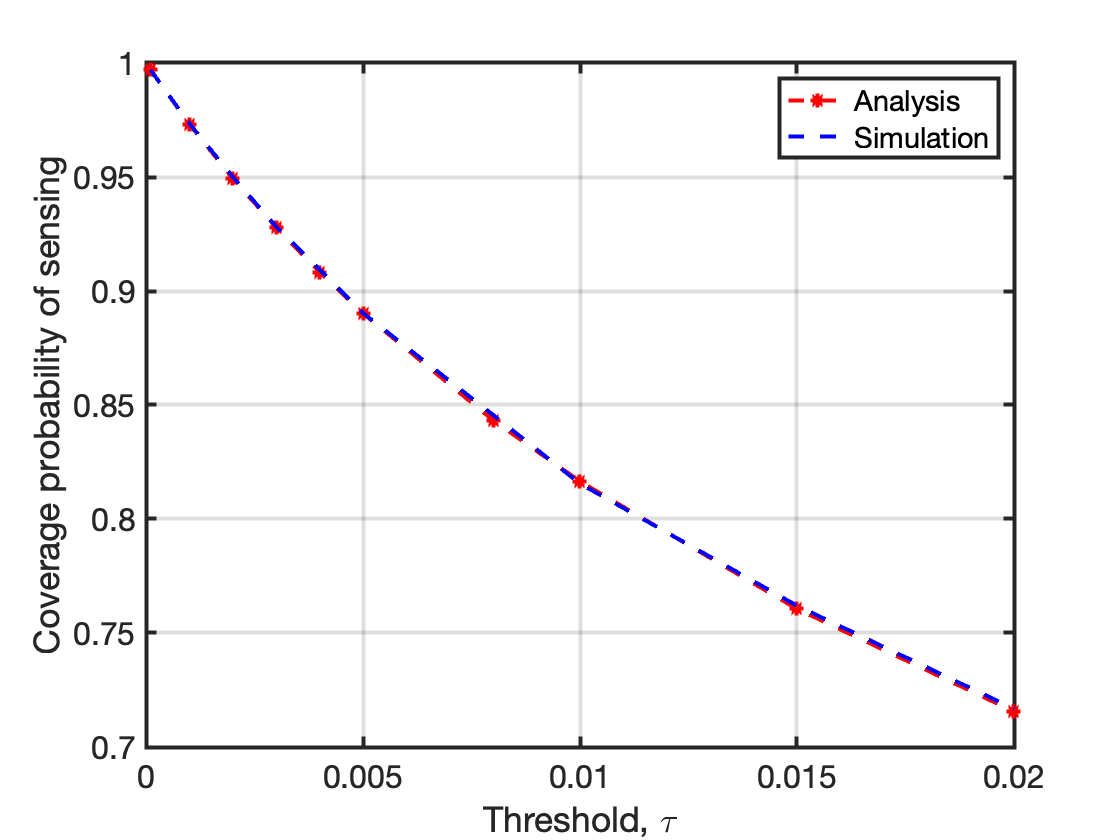


figure();

plot(tau_s_0, Ana_P_s_cov,'--*r','LineWidth',2);hold on;
plot(tau_s_0, Sim_P_s_cov,'--b','LineWidth',2);hold on;

legend('Analysis','Simulation');
xlabel('Threshold, \tau');
ylabel('Coverage probability of sensing' );



set(gca,'LineWidth',2,'FontSize',16);
grid on;